kFactor = 2*pi*B/MATERIAL.CT; % 无量纲频率放大系数

透射系数

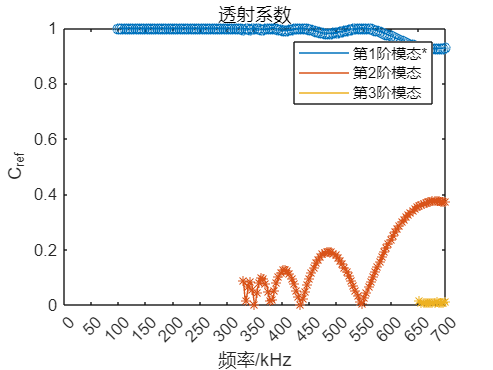

fig(2)=figure;
clear cti pic
ct = zeros(nff,nmode);
legendText = [];
for ii = 1:nff
	tmp = cT{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		ct(ii,imode) = tmp(imode);
	end
end

for imode = 1:nmode
	idx = find(ct(:,imode));
	iff = ff(idx);
	ict = ct(idx,imode);
	ffi = linspace(min(iff),max(iff),1000);
	cti(:,imode) = interp1(iff,ict,ffi,'spline');
	if imode == mode_in
		pic(imode) = plot(ffi/1e3,cti(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/1e3,ict(:),'o','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态*'])];
	else
		pic(imode) = plot(ffi/1e3,cti(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/1e3,ict(:),'*','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态'])];
	end
end
hold off


xlim([0 f/1e3]);	ylim([0 1])
xticks(0:50:f/1e3)
xlabel('频率/kHz')
ylabel('C_{ref}')
legend(pic,legendText)
% legend('1阶透射系数','','2阶透射系数','','3阶透射系数','','Location','northeastoutside')
title('透射系数')

反射系数

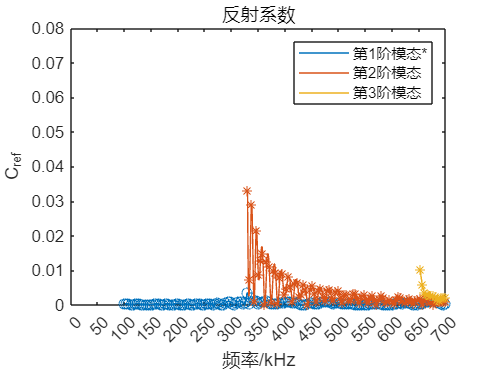

fig(1) = figure;
clear cri pic
cr = zeros(nff,nmode);
legendText = [];
for ii = 1:nff
	tmp = cR{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		cr(ii,imode) = tmp(imode);
	end
end


for imode = 1:nmode
	idx = find(cr(:,imode));
	iff = ff(idx);
	ict = cr(idx,imode);
	ffi = linspace(min(iff),max(iff),1000);
	cri(:,imode) = interp1(iff,ict,ffi,'spline');
	if imode == mode_in
		pic(imode) = plot(ffi/1e3,cri(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/1e3,ict(:),'o','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态*'])];
	else
		pic(imode) = plot(ffi/1e3,cri(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/1e3,ict(:),'*','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode), '阶模态'])];
	end
end
hold off

xlim([0,f/1e3]);	ylim([0 0.08])
xticks(0:50:f/1e3)
xlabel('频率/kHz')
ylabel('C_{ref}')
legend(pic,legendText)
% legend('1阶透射系数','','2阶透射系数','','3阶透射系数','','Location','northeastoutside')
title('反射系数')


error("程序已完成，下面是保存/加载fig")

程序已完成，下面是保存/加载fig

保存fig

savefig(fig,['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'pipe_m1.fig'])

读取fig

openfig(['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'pipe_m1.fig'],'visible')